% Presetting
syms x y z omega phi psi;
PosExtract=[0; 0; 0; 1];
p(x, y, z)=[x; y; z];
Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];
Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];
Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

% Body Kinematics
syms L W omega phi psi xm ym zm;

% Global to Body
anglegmx=omega;
anglegmy=phi;
anglegmz=psi;
pgm=[xm ym zm].';
Rotgm=Rotx(anglegmx)*Roty(anglegmy)*Rotz(anglegmz);
Tgm=HomogeneousTransform(Rotgm, pgm, 1);

% Body to Right Front Shoulder
anglemRFS=pi/2;
pmRFS=[L/2 0 W/2].';
RotmRFS=Roty(anglemRFS);
TmRFS=HomogeneousTransform(RotmRFS, pmRFS, 1);

% Body to Right Back Shoulder
anglemRBS=pi/2;
pmRBS=[-L/2 0 W/2].';
RotmRBS=Roty(anglemRBS);
TmRBS=HomogeneousTransform(RotmRBS, pmRBS, 1);

% Body to Left Front Shoulder
anglemLFS=-pi/2;
pmLFS=[L/2 0 -W/2].';
RotmLFS=Roty(anglemLFS);
TmLFS=HomogeneousTransform(RotmLFS, pmLFS, 1);

% Body to Left Back Shoulder
anglemLBS=-pi/2;
pmLBS=[-L/2 0 -W/2].';
RotmLBS=Roty(anglemLBS);
TmLBS=HomogeneousTransform(RotmLBS, pmLBS, 1);

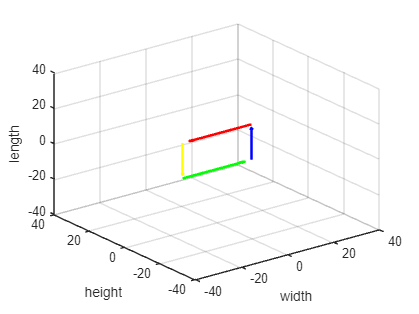

% Body Kinematics test by plot graph

% Global to Body
anglegmx=0;
anglegmy=0;
anglegmz=0;
pgm=[0 0 0].';
Rotgm=Rotx(anglegmx)*Roty(anglegmy)*Rotz(anglegmz);
Tgm=HomogeneousTransform(Rotgm, pgm, 1);

% Body to Left Front Shoulder
anglemRFS=pi/2;
pmRFS=[30/2 0 20/2].';
RotmRFS=Roty(anglemRFS);
TmRFS=HomogeneousTransform(RotmRFS, pmRFS, 1);

% Body to Right Back Shoulder
anglemRBS=pi/2;
pmRBS=[-30/2 0 20/2].';
RotmRBS=Roty(anglemRBS);
TmRBS=HomogeneousTransform(RotmRBS, pmRBS, 1);

% Body to Left Front Shoulder
anglemLFS=-pi/2;
pmLFS=[30/2 0 -20/2].';
RotmLFS=Roty(anglemLFS);
TmLFS=HomogeneousTransform(RotmLFS, pmLFS, 1);

% Body to Left Back Shoulder
anglemLBS=-pi/2;
pmLBS=[-30/2 0 -20/2].';
RotmLBS=Roty(anglemLBS);
TmLBS=HomogeneousTransform(RotmLBS, pmLBS, 1);

TgRFS=Tgm*TmRFS;
TgRBS=Tgm*TmRBS;
TgLFS=Tgm*TmLFS;
TgLBS=Tgm*TmLBS;

pgRFS=TgRFS*PosExtract;
pgRBS=TgRBS*PosExtract;
pgLFS=TgLFS*PosExtract;
pgLBS=TgLBS*PosExtract;

front=pgRFS-pgLFS;
right=pgRBS-pgRFS;
back=pgLBS-pgRBS;
left=pgLFS-pgLBS;

figure
quiver3(pgLFS(1,1), pgLFS(2,1), pgLFS(3,1), front(1,1), front(2,1), front(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgRFS(1,1), pgRFS(2,1), pgRFS(3,1), right(1,1), right(2,1), right(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgRBS(1,1), pgRBS(2,1), pgRBS(3,1), back(1,1), back(2,1), back(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgLBS(1,1), pgLBS(2,1), pgLBS(3,1), left(1,1), left(2,1), left(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Left Front Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Left Front Shoulder to Preprocessing UpperArm
angle01=theta1;
p01=p(0,0,-L1);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Left Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=-pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Left Front UpperArm to LowArm
angle23=theta2;
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),-L2z);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Left Front LowArm to Foot
angle34=theta3;
p34=p(L3*cos(theta3),L3*sin(theta3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Left Front Shoulder to UpperArm
T02=T01*T12;
T02=simplify(T02);
% Left Front Shoulder to LowArm
T03=T02*T23;
T03=simplify(T03);
% Left Front Shoulder to Foot
T04=T03*T34;
T04=simplify(T04);

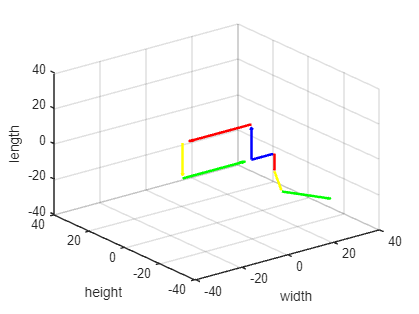

% Left Front Leg Kinematics test by plot graph

% Left Front Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,-10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Left Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=-pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Left Front UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),-10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Left Front LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Left Front Shoulder to UpperArm
T02=T01*T12;
% Left Front Shoulder to LowArm
T03=T02*T23;
% Left Front Shoulder to Foot
T04=T03*T34;

pgLFU=TgLFS*T01*PosExtract;
pgLFL1=TgLFS*T02*[0 0 -10 1].';
pgLFL2=TgLFS*T03*PosExtract;
pgLFF=TgLFS*T04*PosExtract;

LFS=pgLFU-pgLFS;
LFU=pgLFL1-pgLFU;
LFL1=pgLFL2-pgLFL1;
LFL2=pgLFF-pgLFL2;

quiver3(pgLFS(1,1), pgLFS(2,1), pgLFS(3,1), LFS(1,1), LFS(2,1), LFS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgLFU(1,1), pgLFU(2,1), pgLFU(3,1), LFU(1,1), LFU(2,1), LFU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgLFL1(1,1), pgLFL1(2,1), pgLFL1(3,1), LFL1(1,1), LFL1(2,1), LFL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgLFL2(1,1), pgLFL2(2,1), pgLFL2(3,1), LFL2(1,1), LFL2(2,1), LFL2(3,1), 'Color', 'green','LineWidth', 2)
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])